# ii)


clear all close all
n = 5000;
sample = zeros(1,n);
uni = makedist('Uniform','lower',0,'upper',1);
for i = 1:n
    sample(i) = logninv(random(uni),3,1);
end


%%% b)
mon_val_ra = sqrt(sample);
mon_val_rs = sample.^3;

Eu_ra = mean(mon_val_ra)

Eu_ra = 5.0097

Eu_rs = mean(mon_val_rs)

Eu_rs = 4.0929e+05


CE_ra = Eu_ra^2

CE_ra = 25.0973

CE_rs = Eu_rs^(1/3)

CE_rs = 74.2465


E = mean(sample)

E = 31.9162


RP_ra = E - CE_ra

RP_ra = 6.8189

RP_rs = E - CE_rs

RP_rs = -42.3303

%%% c)
VaR = prctile(sample,10)

VaR = 5.4008

TailIndixes = find(sample<=VaR);
CVaR = mean(sample(TailIndixes))

CVaR = 3.6180

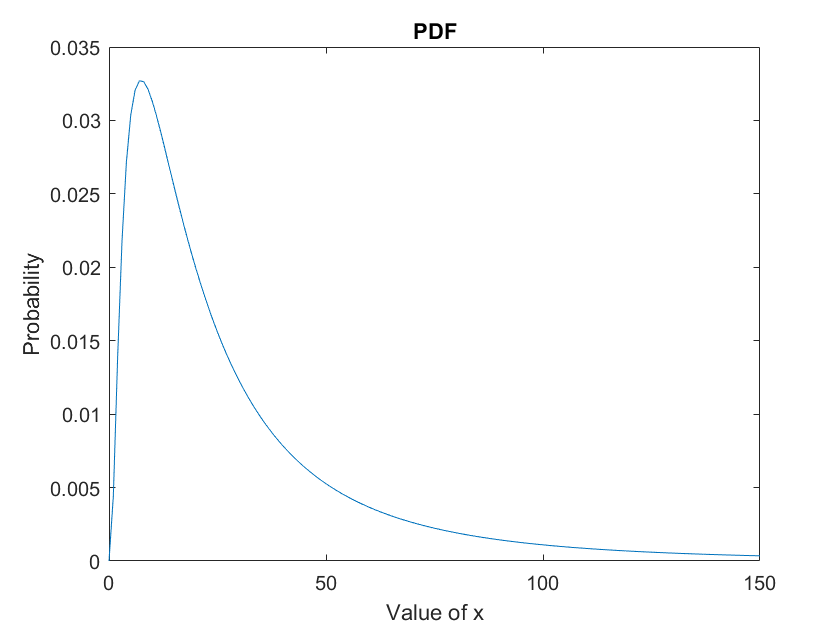

%%% extra
t = 0:150;
pd = makedist('Lognormal','mu',3,'sigma',1);
a = pdf(pd,t);
b = cdf(pd,t);
figure
plot(t,a)
title("PDF")
ylabel("Probability")
xlabel("Value of x")

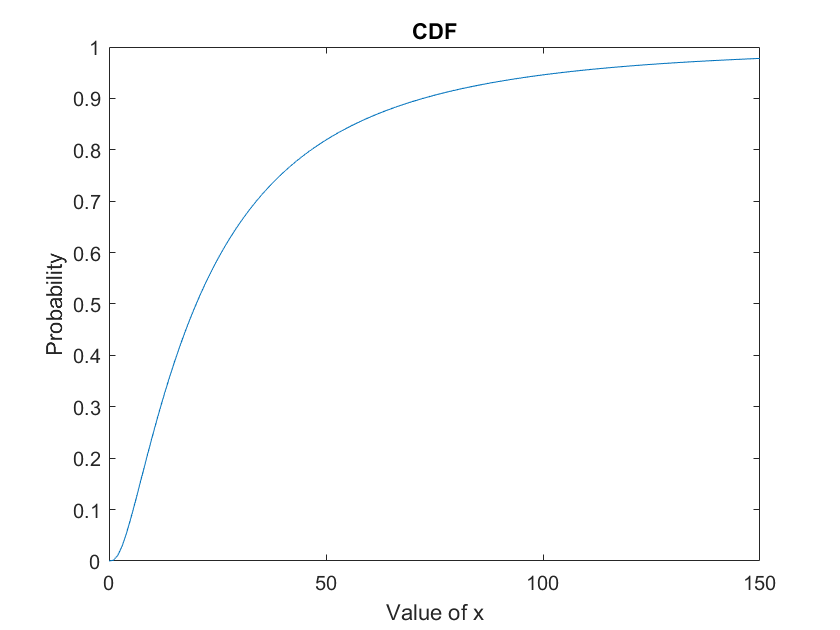

figure
plot(t,b)
title("CDF")
ylabel("Probability")
xlabel("Value of x")

## iii

%%% b)
clear all, close all
prob = [0.05 0.05 0.1 0.2 0.3 0.15 0.1 0.05]';
mon_val = [5 10 50 80 100 130 170 200]';

mon_val_ra = sqrt(mon_val);
mon_val_rs = mon_val.^3;

Eu_ra = prob'*mon_val_ra

Eu_ra = 9.4871

Eu_rs = prob'*mon_val_rs

Eu_rs = 1.6358e+06


CE_ra = Eu_ra^2

CE_ra = 90.0049

CE_rs = Eu_rs^(1/3)

CE_rs = 117.8268


E = prob'*mon_val

E = 98.2500


RP_ra = E - CE_ra

RP_ra = 8.2451

RP_rs = E - CE_rs

RP_rs = -19.5768

%%% c)
alpha =0.10;
cdf = cumsum(prob)';
VaR = mon_val(cdf == alpha)

VaR = 10

CVaR = prob(1:2)'*mon_val(1:2)/sum(prob(1:2))

CVaR = 7.5000